clear; clc

## Constants

apo_time    = 28;                       % [s]
main_time   = 163;                      % [s]
           
apo_height  = 10812 / 3.281;            % [m]
main_height = 500 / 3.281;              % [m]

m           = (10886.2 - 2516)/1000;    % [kg]

rho_const = 1.225; % [kg m^-3]

## Calculations

drogue_time = main_time - apo_time;     % [s]
drogue_dist = apo_height - main_height; % [m]
a_g         = 9.8;                      % [m s^-1]
F_g         = a_g*m;                    % [N]

## Constant $C_d S$, Constant $\rho \;$

The force of drag is given by


$$F_d=\frac{1}{2}\rho V^2\cdot C_dS=a_d\cdot m$$


So


$$C_dS=\frac{2a_dm}{\rho * V^2}$$


Now, we can find terminal velocity by setting acceleration to zero, meaning the force of drag is equal to the force of gravity.


$$a_d =a_g \to F_d =F_g$$


And using $F_d=\frac{1}{2}\rho V^2\cdot C_dS$,


$$V_\text{term}=\sqrt{\frac{2F_g}{\rho C_dS}$$


Now we can also find the time required to reach terminal velocity. First, use the expression for velocity in terms of acceleration:


$$V=at$$


And we also know


$$a = \frac{1}{2}\rho V^2 \cdot C_dS$$


So,


$$V= \big(\frac{1}{2}\rho V^2 \cdot C_dS\big)\cdot t$$


Solving for time, we find


$$t = \frac{2Vm}{\rho V^2 \cdot C_dS}
$$



$$t = \frac{2m}{VC_dS$$


Now, the time to reach terminal velocity is given by


$$t_\text{term} = \frac{2m}{C_dS \sqrt{\frac{2F_g}{\rho C_dS}$$


Knowing the total time between apogee and main parachute deploy, we can find the duration the system is falling at terminal velocity under drogue


$$T_\text{term}=T_\text{total}-t_\text{term}$$


Which also lets us know the total displacement of the system at terminal velocity:


$$u_\text{term}=T_\text{term}\cdot V_\text{term}$$


With a constant $C_d S$, we can also solve for velocity as a function of time:


$$V= \big(\frac{1}{2}\rho V^2 \cdot C_dS\big)\cdot t\rightarrow V=\frac{2}{\rho\cdot C_dS\cdot t$$


The displacement is the integral of this with respect to time, or


$$u_\text{accel}=\ln\bigg(\frac{2}{\rho\cdot C_dS}\cdot t\bigg)\bigg|_{t_\text{term}}=\ln\bigg(\frac{2}{\rho\cdot C_dS}\cdot t_\text{term}\bigg)$$


We also know the total displacement must be equal to


$$u_\text{total}=u_\text{accel}+u_\text{term}$$


So


$$u_\text{total}=\ln\bigg(\frac{2}{\rho\cdot C_dS}\cdot t_\text{term}\bigg)+T_\text{term}\cdot V_\text{term}$$


Expanding all of this, we find


$$u_\text{total}=\ln\Bigg(\frac{2}{\rho\cdot C_dS}\cdot \frac{2m}{C_dS \sqrt{\frac{2F_g}{\rho C_dS}}}\Bigg)
+
\Bigg(T_\text{total} - \frac{2m}{C_dS \sqrt{\frac{2F_g}{\rho C_dS}}}\Bigg)\cdot \sqrt{\frac{2F_g}{\rho C_dS}$$


We now have an equation containing only one unknown, which is $C_d S$. This is best solved numerically, but we can also plot it for funsies.

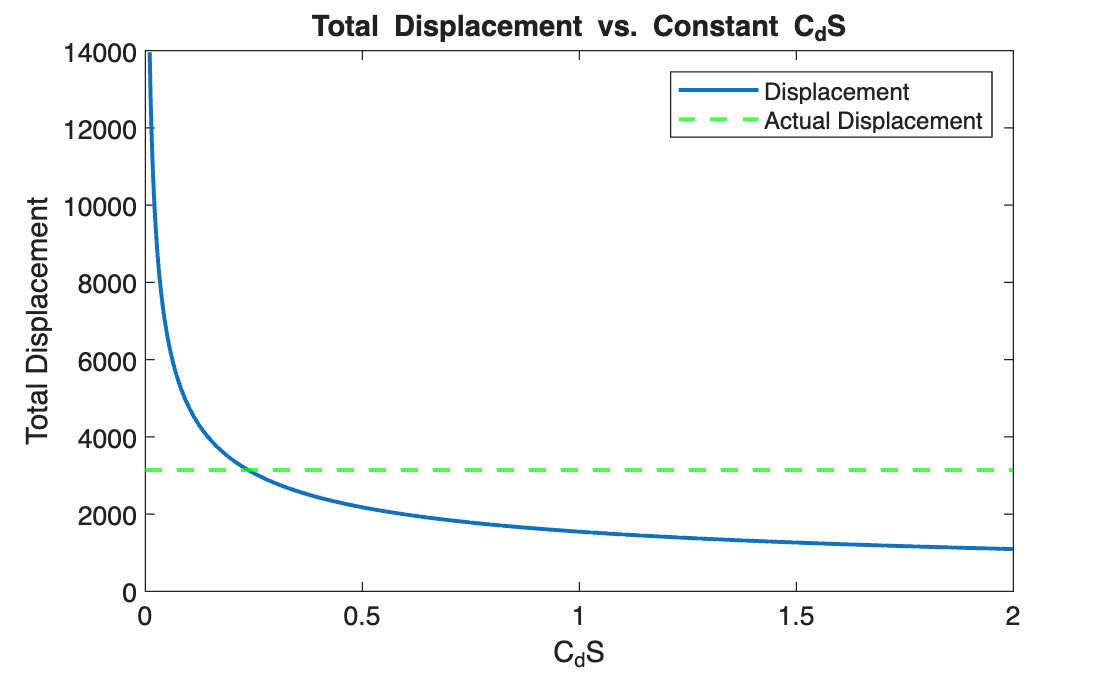

step = 0.01;
CdS = linspace(step, 2, 1000);

u_total = @(T_total, rho, Fg, m, CdS)...
    log(2./(rho*CdS) .* 2*m ./ (CdS .* sqrt((2*Fg) ./ (rho*CdS))))+...
    (T_total - (2*m) ./ (CdS .* sqrt((2*Fg) ./ (rho*CdS)))) .* sqrt((2*Fg) ./ (rho*CdS));

u_totals = u_total(drogue_time, rho_const, F_g, m, CdS);
clf
plot(CdS, u_totals, 'DisplayName', 'Displacement', 'LineWidth', 1.5); hold on
yline(drogue_dist, '--g', 'DisplayName', 'Actual Displacement', 'LineWidth', 1.5)
legend
xlabel("C_dS")
ylabel("Total Displacement")
title("Total Displacement vs. Constant C_dS")

Solving numerically, we find

CdS_const = fsolve(@(x) u_total(drogue_time, rho_const, F_g, m, x) - drogue_dist, 1, optimoptions('fsolve', 'Display', 'off'))

CdS_const = 0.2368

We also find the terminal velocity is

V_term = terminal_vel(m, CdS_const, rho_const)

V_term = 23.7945